# **WM9QE: Applied Statistics for Artificial Intelligence**

**Non-Linear Regression - Independent Exercises**

This live script includes the extra examples  week 3  **Non-Linear Regression**. Full detail of the lectures and examples are availabe on the Moodle page here [Section: Week Three | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=621569)

# EXAMPLE Binary Logistic Regression

The products produced by a process are classified as either accepted (1) or defects (0) by the customers. The response depends on two quality characteristics; the weight (g) and the diameter (cm) of the product. In order to model the relationship, the quality manager collected a sample of 15 products. What is the expected response for a product that weights 150 g and has a diameter of 3.31cm?

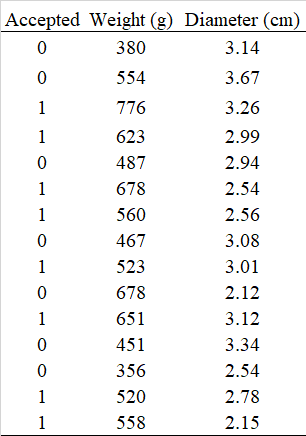

%% LOGISTIC REGRESSION: Weight & Diameter → Acceptance Probability

clc; clear; close all;

fprintf('\n=== LOGISTIC REGRESSION FOR DEFECT CLASSIFICATION ===\n');


=== LOGISTIC REGRESSION FOR DEFECT CLASSIFICATION ===



%% Step 1. Data
Accepted = [0 0 1 1 0 1 1 0 1 0 1 0 0 1 1]';
Weight   = [380 554 776 623 487 678 560 467 523 678 651 451 356 520 558]';
Diameter = [3.14 3.67 3.26 2.99 2.94 2.54 2.56 3.08 3.01 2.12 3.12 3.34 2.54 2.78 2.15]';

data = table(Accepted, Weight, Diameter)

data = 15×3 table
    Accepted    Weight    Diameter
    ________    ______    ________

       0         380        3.14  
       0         554        3.67  
       1         776        3.26  
       1         623        2.99  
       0         487        2.94  
       1         678        2.54  
       1         560        2.56  
       0         467        3.08  
       1         523        3.01  
       0         678        2.12  
       1         651        3.12  
       0         451        3.34  
       0         356        2.54  
       1         520        2.78  
       1         558        2.15  



%% Step 2. Fit Logistic Regression Model
model = fitglm(data, 'Accepted ~ Weight + Diameter', ...
    'Distribution','binomial','Link','logit');

disp('=== Model Summary (Logistic Regression) ===');

=== Model Summary (Logistic Regression) ===


disp(model);


Generalized linear regression model:
    logit(Accepted) ~ 1 + Weight + Diameter
    Distribution = Binomial

Estimated Coefficients:
                   Estimate       SE         tStat       pValue 
                   ________    _________    ________    ________

    (Intercept)      -5.353        6.725    -0.79599     0.42604
    Weight          0.01431    0.0079947      1.7899    0.073473
    Diameter       -0.79434       1.5895    -0.49973     0.61726


15 observations, 12 error degrees of freedom
Dispersion: 1
Chi^2-statistic vs. constant model: 6.17, p-value = 0.0457



%% Step 3. Extract coefficients + odds ratios
b = model.Coefficients.Estimate;
OR = exp(b);

CoefSummary = table(model.Coefficients.Estimate, model.Coefficients.pValue, OR, ...
    'VariableNames', {'Estimate','pValue','OddsRatio'}, ...
    'RowNames', {'Intercept','Weight','Diameter'});

disp('=== Coefficient Significance + Odds Ratios ===');

=== Coefficient Significance + Odds Ratios ===


disp(CoefSummary);

                 Estimate     pValue     OddsRatio
                 ________    ________    _________

    Intercept      -5.353     0.42604    0.0047338
    Weight        0.01431    0.073473       1.0144
    Diameter     -0.79434     0.61726      0.45188




%% Step 4. Add predicted logs, probabilities, log-likelihood
X = [ones(height(data),1), Weight, Diameter];
L = X * b;
p_hat = exp(L)./(1+exp(L));
LL = Accepted.*log(p_hat) + (1-Accepted).*log(1-p_hat);

data.Logit_L = L;
data.Prob = p_hat;
data.LL = LL;

disp('=== Data with Predicted Probabilities ===');

=== Data with Predicted Probabilities ===


disp(data);

    Accepted    Weight    Diameter    Logit_L       Prob         LL    
    ________    ______    ________    ________    ________    _________

       0         380        3.14       -2.4096    0.082444    -0.086042
       0         554        3.67      -0.34071     0.41564     -0.53723
       1         776        3.26        3.1617     0.95937    -0.041481
       1         623        2.99        1.1868     0.76617     -0.26635
       0         487        2.94      -0.71959     0.32748     -0.39673
       1         678        2.54        2.3313     0.91144    -0.092735
       1         560        2.56       0.62686     0.65178     -0.42805
       0         467        3.08        -1.117     0.24657     -0.28312
       1         523        3.01      -0.26005     0.43535      -0.8316
   


%% Step 5. Prediction for a new observation

newPoint = table(150, 3.31, 'VariableNames', {'Weight','Diameter'});
[p_pred, CI] = predict(model, newPoint);

fprintf('\nPrediction for (W=150g, D=3.31cm):\n');


Prediction for (W=150g, D=3.31cm):


fprintf('Probability of Acceptance = %.4f\n', p_pred);

Probability of Acceptance = 0.0029


fprintf('Probability of Defect     = %.4f\n', 1-p_pred);

Probability of Defect     = 0.9971



binary_class = p_pred >= 0.5;
fprintf('Predicted class (1=Accepted,0=Defect): %d\n', binary_class);

Predicted class (1=Accepted,0=Defect): 0



fprintf('\n95%% Confidence Interval for Mean Probability:\n');


95% Confidence Interval for Mean Probability:


disp(CI);

    0.0000    0.5899



# EXAMPLE  Quadratic Regression Exercise

Suppose we are interested in understanding the relationship between number of hours worked and reported happiness. We have the following data on the number of hours worked per week and the reported happiness level (on a scale of 0-100) for 11 different people:

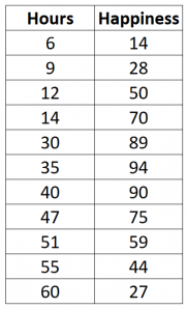

- Create a dataframe with the provided data.

- Visualise the data

- Fit a quadratic regression model and visualise the results

- Evaluate your model

- Predict the happiness value for the 70 and 75 hours of working

- Compare your results with the results on the following link: [https://www.statology.org/quadratic-regression-r/](https://www.statology.org/quadratic-regression-r/)

Reference: [https://www.statology.org/quadratic-regression-r/](https://www.statology.org/quadratic-regression-r/)

## Step 0. Initialisation

clc; clear; close all; 

## Step 1. Input Data

% Data: Weekly working hours vs reported happiness level (0-100)
hours = [6; 9; 12; 14; 30; 35; 40; 47; 51; 55; 60];
happiness = [14; 28; 50; 70; 89; 94; 90; 75; 59; 44; 27];

Data = table(hours, happiness)

Data = 11×2 table
    hours    happiness
    _____    _________

      6         14    
      9         28    
     12         50    
     14         70    
     30         89    
     35         94    
     40         90    
     47         75    
     51         59    
     55         44    
     60         27    


summary(Data)


Data: 11×2 table

Variables:

    hours: double
    happiness: double

Statistics for applicable variables:

                 NumMissing     Min      Median     Max         Mean            Std    

    hours            0            6        35        60        32.6364        19.7498  
    happiness        0           14        59        94        58.1818        27.8777  




n = height(Data); % sample size

## Step 2. Choose Regression Model: Visual inspection (Linearity vs Nonlinearity)

Is a straight line reasonable?

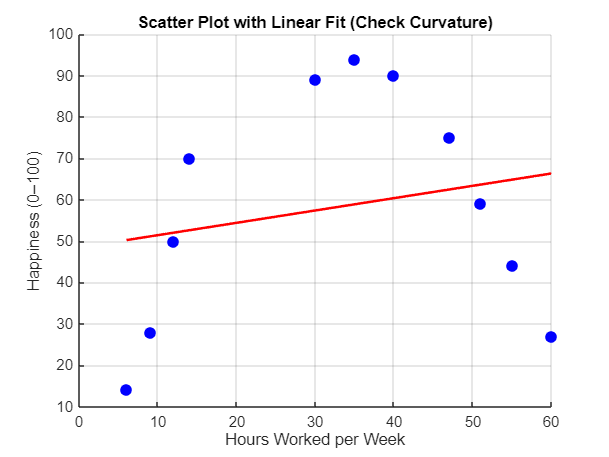

figure('Color','w');
scatter(hours, happiness, 60,'b','filled'); hold on; grid on;

% Linear reference
p_lin = polyfit(hours, happiness, 1);
xfit = linspace(min(hours), max(hours), 200)';
yfit_lin = polyval(p_lin, xfit);
plot(xfit, yfit_lin,'r-','LineWidth',1.7);

xlabel('Hours Worked per Week');
ylabel('Happiness (0–100)');
title('Scatter Plot with Linear Fit (Check Curvature)');

**Interpretation:** Clear curve → diminishing returns.

## Step 3. Quadratic Model Fit


$$\mathrm{Happiness}=a\ldotp {\mathrm{Hours}}^2 +b\ldotp \mathrm{Hours}+c$$


Xquad = [hours.^2, hours, ones(n,1)];
coef = Xquad \ happiness; % OLS coefficients

a = coef(1); b = coef(2); c = coef(3);

yhat = Xquad * coef;
res = happiness - yhat;

fprintf('\nQuadratic Model:\n');


Quadratic Model:


fprintf('ŷ = %.6f·h^2 + %.4f·h + %.3f\n', a, b, c);

ŷ = -0.101200·h^2 + 6.7444·h + -18.254


## Step 4. Model Visualisation

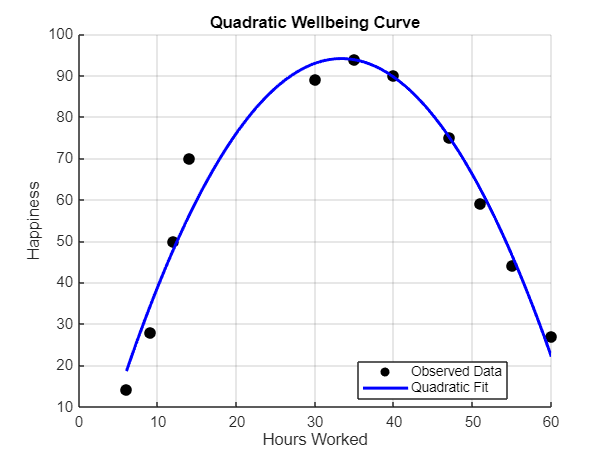

 figure('Color','w'); hold on; grid on;
scatter(hours, happiness, 60,'k','filled','DisplayName','Observed Data');

xgrid = linspace(min(hours), max(hours),400)';
plot(xgrid, [xgrid.^2 xgrid ones(size(xgrid))]*coef, ...
    'b-','LineWidth',2,'DisplayName','Quadratic Fit');

xlabel('Hours Worked'); ylabel('Happiness');
title('Quadratic Wellbeing Curve');
legend('Location','best');

## Step 5. Predictive Power

Model Evaluation Metrics

- R² → Proportion of explained variance

- Adj R² → Penalizes unnecessary complexity

SST = sum((happiness - mean(happiness)).^2);
SSE = sum(res.^2);
SSR = SST - SSE;

p = 2;
df_reg = p;
df_res = n - p - 1;
MSR = SSR / df_reg;
MSE = SSE / df_res;

R2  = 1 - SSE/SST;
AdjR2 = 1 - (1-R2)*(n-1)/(n-p-1);

fprintf('\nR² = %.4f, Adjusted R² = %.4f\n', R2, AdjR2);


R² = 0.9602, Adjusted R² = 0.9502


**I**High R² expected → strong nonlinear fit.

## Step 6. Significance of Model (P-Value, ANOVA)

Hypotheses for ANOVA  F-Test (overall model):

- 
$$H_0 :a=b=0\;$$


- $H_1 :$ At least one of $a\;\textrm{or}\;b\not= 0$ 

Fstat = MSR / MSE;
pF = 1 - fcdf(Fstat, df_reg, df_res);

Cov = MSE * pinv(Xquad' * Xquad);
se = sqrt(diag(Cov));
tcoef = coef ./ se;
pcoef = 2*(1 - tcdf(abs(tcoef), df_res));

ANOVA = table([df_reg; df_res; df_reg+df_res], [SSR; SSE; SST], ...
    [MSR; MSE; NaN], [Fstat;NaN;NaN], [pF;NaN;NaN], ...
    'VariableNames',{'df','SS','MS','F','pValue'}, ...
    'RowNames',{'Regression','Residual','Total'});
disp(ANOVA);

                  df      SS        MS        F         pValue  
                  __    ______    ______    ______    __________

    Regression     2    7462.3    3731.1    96.493    2.5102e-06
    Residual       8    309.34    38.668       NaN           NaN
    Total         10    7771.6       NaN       NaN           NaN




CoefTable = table({'hours^2';'hours';'intercept'}, coef, se, tcoef, pcoef, ...
    'VariableNames',{'Term','Estimate','StdErr','tStat','pValue'});
disp(CoefTable);

        Term         Estimate     StdErr       tStat       pValue  
    _____________    ________    _________    _______    __________

    {'hours^2'  }    -0.1012     0.0074601    -13.565    8.3788e-07
    {'hours'    }     6.7444       0.48552     13.891    6.9788e-07
    {'intercept'}    -18.254        6.1851    -2.9512      0.018391



Both linear and squared terms should be significant.

## Step 7. Normality Test of Residuals 

Null vs. Alternative:

- $H_0$:Residuals follow a Normal distribution

- $H_1$:Residuals are NOT normally distributed

**7.1 Generate Residuals Table**

Obs = (1:n)';
ResidualsTable = table(Obs, yhat, res, ...
    'VariableNames', {'Observation','FittedValue','Residual'});
disp('Residuals Table:');

Residuals Table:


disp(ResidualsTable);

    Observation    FittedValue    Residual
    ___________    ___________    ________

         1           18.569        -4.5693
         2           34.248        -6.2484
         3           48.106         1.8941
         4           56.332         13.668
         5           92.997        -3.9974
         6           93.829        0.17064
         7           89.601        0.39871
         8           75.181       -0.18122
         9           62.488        -3.4884
        10           46.557        -2.5572
        11           22.089         4.9108



**7.2 Descriptive Statistics of Residuals**

mu_r    = mean(res);               % should be near 0
sigma_r = std(res);                % standard deviation of residuals
Q1      = quantile(res, 0.25);
Q3      = quantile(res, 0.75);
IQR     = Q3 - Q1;                 % interquartile range
LB      = Q1 - 1.5*IQR;            % lower bound (Tukey method)
UB      = Q3 + 1.5*IQR;            % upper bound (Tukey method)
res_range = range(res);

ResidStats = table(mu_r, sigma_r, Q1, Q3, IQR, LB, UB, res_range, ...
    'VariableNames', {'Mean','StdDev','Q1','Q3','IQR','LowerBound','UpperBound','Range'});
disp('Descriptive Statistics of Residuals:');

Descriptive Statistics of Residuals:


disp(ResidStats);

       Mean        StdDev      Q1         Q3       IQR      LowerBound    UpperBound    Range 
    ___________    ______    _______    ______    ______    __________    __________    ______

    -4.3279e-14    5.5618    -3.8702    1.5202    5.3904     -11.956        9.6059      19.916



**7.3 Boxplot for Outlier Detection**

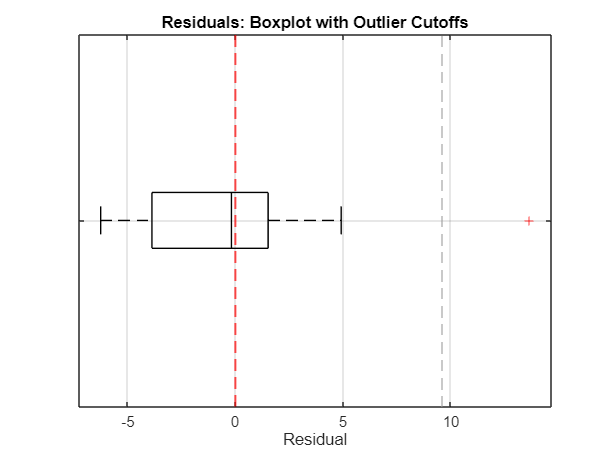

figure('Color','w');
boxplot(res, 'orientation','horizontal', 'Whisker',1.5, 'Colors','k');
hold on;
xline(mu_r, 'r--', 'LineWidth',1.3, 'DisplayName','Mean Residual');
xline(LB, '--', 'Color',[0.6 0.6 0.6], 'DisplayName','Lower Bound');
xline(UB, '--', 'Color',[0.6 0.6 0.6], 'DisplayName','Upper Bound');
title('Residuals: Boxplot with Outlier Cutoffs');
xlabel('Residual'); set(gca,'YTickLabel',{' '});
grid on; hold off;

Interpretation:

-   Mean near 0 → unbiased model

- Symmetric box → likely normality

- Few outliers beyond bounds → acceptable distribution

**7.4 Chi-Square Goodness-of-Fit Test for Normality**

fprintf('\nChi-Square Normality Test Setup:\n');


Chi-Square Normality Test Setup:



k = ceil(1 + 3.322 * log10(n));          % Sturges Rule for number of bins
range_res = range(res);
class_width = range_res / k;
fprintf('Classes = %d, Class Width = %.4f\n', k, class_width);

Classes = 5, Class Width = 3.9832



% Observed frequencies (histogram)
[Observed, bin_edges] = histcounts(res, k);

% Expected frequencies (under N(mu, sigma))
cdf_vals = normcdf(bin_edges, mu_r, sigma_r);
Expected = diff(cdf_vals) * n;
Expected(Expected == 0) = eps;           % avoid division by zero

% Chi-Square statistic
ChiVals = (Observed - Expected).^2 ./ Expected;
ChiSq_stat = sum(ChiVals);

% Degrees of freedom: bins - 1 (sum constraint) - 2 (mean, std estimated)
df_chi = k - 1 - 2;
p_chi = 1 - chi2cdf(ChiSq_stat, df_chi);

ChiSqTable = table((1:k)', Observed', Expected', ChiVals', ...
    'VariableNames', {'Bin','Observed','Expected','ChiSq'});
disp('Chi-Square Goodness-of-Fit Table:');

Chi-Square Goodness-of-Fit Table:


disp(ChiSqTable);

    Bin    Observed    Expected      ChiSq   
    ___    ________    ________    __________

     1        2         2.0152     0.00011465
     2        6         3.6886         1.4483
     3        2         3.1714         0.4327
     4        0           1.28           1.28
     5        1        0.24166         2.3798




fprintf('Chi-Square = %.3f, df = %d, p-value = %.4f\n', ChiSq_stat, df_chi, p_chi);

Chi-Square = 5.541, df = 2, p-value = 0.0626


if p_chi > 0.05
    fprintf('Decision: Fail to reject H0 → residuals consistent with Normality ✓\n');
else
    fprintf('Decision: Reject H0 → evidence residuals NOT normal ✗\n');
end

Decision: Fail to reject H0 → residuals consistent with Normality ✓


**7.5 Visual Normality Checks**

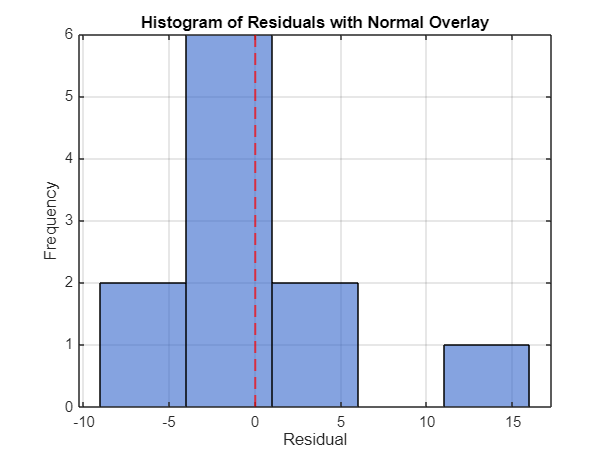

figure('Color','w');
histogram(res, 'BinEdges', bin_edges, 'FaceColor',[0.2 0.4 0.8],'FaceAlpha',0.6);
xline(mu_r, 'r--', 'LineWidth',1.3, 'DisplayName','Mean');
title('Histogram of Residuals with Normal Overlay');
xlabel('Residual'); ylabel('Frequency');
grid on;

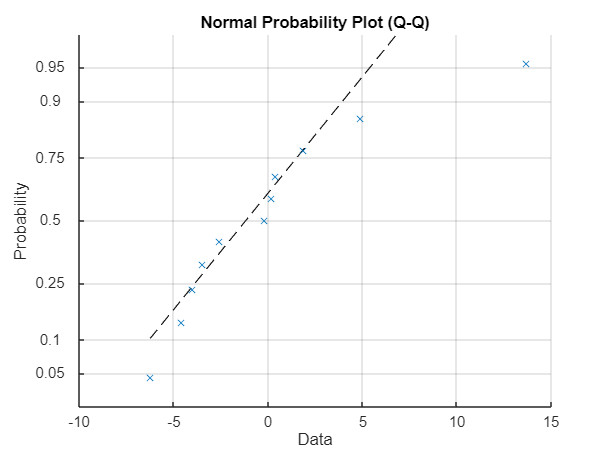


% Q-Q (Normal Probability) Plot
figure('Color','w');
probplot('normal', res);
title('Normal Probability Plot (Q-Q)');
grid on;


% Theory:
%   • If residuals are normal → points fall on diagonal
%   • p > 0.05 → Normality assumption satisfied

fprintf('\nInterpretation:\n');


Interpretation:


fprintf('If the residuals follow an approximately normal pattern and p > 0.05,\n');

If the residuals follow an approximately normal pattern and p > 0.05,


fprintf('the model’s inference (ANOVA, t-tests, intervals) remains valid.\n');

the model’s inference (ANOVA, t-tests, intervals) remains valid.


## Step 8. Residual Plots: Constant Variance and Independence Assumption

**Plot 1. Residuals vs Fitted Values (Homoskedasticity Check)**

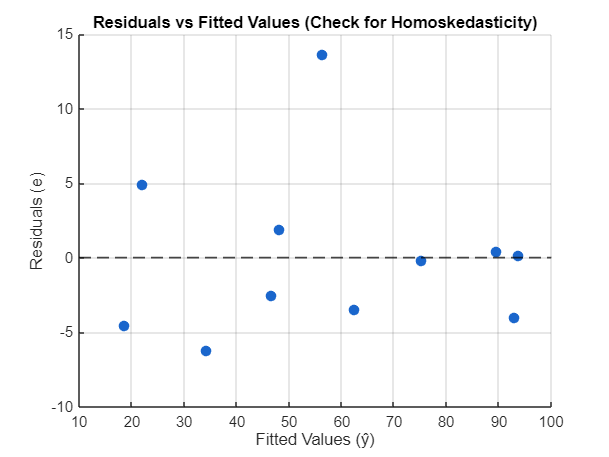

figure('Color','w');
scatter(yhat, res, 50, 'filled', 'MarkerFaceColor',[0.1 0.4 0.8]); hold on;
yline(0, 'k--', 'LineWidth', 1.2);
xlabel('Fitted Values (ŷ)');
ylabel('Residuals (e)');
title('Residuals vs Fitted Values (Check for Homoskedasticity)');
grid on;


% Interpretation guidelines (for class discussion)
fprintf('\nInterpretation — Homoskedasticity Plot:\n');


Interpretation — Homoskedasticity Plot:


fprintf('  ✓ Random cloud around zero → constant variance likely valid.\n');

  ✓ Random cloud around zero → constant variance likely valid.


fprintf('  ✗ Funnel (spread increasing or decreasing) → heteroskedasticity.\n');

  ✗ Funnel (spread increasing or decreasing) → heteroskedasticity.


fprintf('  ✗ Curve pattern → model form may be misspecified.\n');

  ✗ Curve pattern → model form may be misspecified.


**Plot 2. Residuals vs Observation Order (Independence Check)**

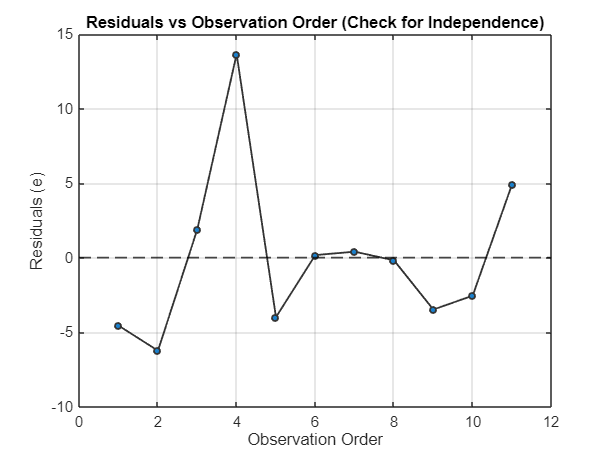

figure('Color','w');
plot(1:n, res, '-o', 'MarkerSize', 4, 'LineWidth', 1.2, ...
    'Color', [0.2 0.2 0.2], 'MarkerFaceColor', [0.1 0.5 0.8]);
yline(0, 'k--', 'LineWidth', 1.2);
xlabel('Observation Order');
ylabel('Residuals (e)');
title('Residuals vs Observation Order (Check for Independence)');
grid on;


fprintf('\nInterpretation — Independence Plot:\n');


Interpretation — Independence Plot:


fprintf('  ✓ Random oscillation around zero → independence supported.\n');

  ✓ Random oscillation around zero → independence supported.


fprintf('  ✗ Upward/downward trend → autocorrelation (time dependency).\n');

  ✗ Upward/downward trend → autocorrelation (time dependency).


fprintf('  ✗ Sudden jumps or blocks → data collected in clusters (batch effects).\n');

  ✗ Sudden jumps or blocks → data collected in clusters (batch effects).


## Step 9. Predictions 


% --- 9.1 Ensure RSE is available
if exist('StdErr','var')
    RSE = StdErr;                   % From Step 5
else
    RSE = sqrt(MSE);                % Fallback definition
end

% --- 9.2 Prediction configuration
alpha = 0.05;                       % 95% prediction level
tcrit = tinv(1 - alpha/2, df_res);  % t critical value
x_new_vals = [70; 75];              % Hours to predict for
k = numel(x_new_vals);

% --- 9.3 Preallocate storage
PointPred   = zeros(k,1);
SE_Pred_py  = zeros(k,1);           % SE = 1.1 × RSE
LowerBound  = zeros(k,1);
UpperBound  = zeros(k,1);

for i = 1:k
    x = x_new_vals(i);
    x_vec = [x.^2, x, 1];           % Design row consistent with model
    PointPred(i) = x_vec * coef;    % Mean prediction
    SE_Pred_py(i) = 1.1 * RSE;      % Approx. constant SE
    LowerBound(i) = PointPred(i) - tcrit * SE_Pred_py(i);
    UpperBound(i) = PointPred(i) + tcrit * SE_Pred_py(i);
end

ErrorTerm     = tcrit .* SE_Pred_py;          
IntervalWidth = UpperBound - LowerBound;

PredictionSummary = table( ...
    x_new_vals, PointPred, SE_Pred_py, ErrorTerm, ...
    LowerBound, UpperBound, IntervalWidth, ...
    'VariableNames', {'Hours','Predicted_Happiness','SE_Pred', ...
                      'ErrorTerm','LowerBound','UpperBound','IntervalWidth'});

disp('=== Prediction Summary ===');

=== Prediction Summary ===


disp(PredictionSummary);

    Hours    Predicted_Happiness    SE_Pred    ErrorTerm    LowerBound    UpperBound    IntervalWidth
    _____    ___________________    _______    _________    __________    __________    _____________

     70            -42.027          6.8402      15.773         -57.8       -26.253         31.547    
     75            -81.675          6.8402      15.773       -97.448       -65.901         31.547    




fprintf('\nInterpretation:\n');


Interpretation:


fprintf('• Uses RSE × 1.1 for Excel-style adjusted prediction uncertainty.\n');

• Uses RSE × 1.1 for Excel-style adjusted prediction uncertainty.


fprintf('• t(df=%d) critical value ensures 95%% prediction coverage.\n', df_res);

• t(df=8) critical value ensures 95% prediction coverage.


fprintf('• Band width remains constant across X → ignores leverage effect.\n');

• Band width remains constant across X → ignores leverage effect.


**Visualisation of Predictions**

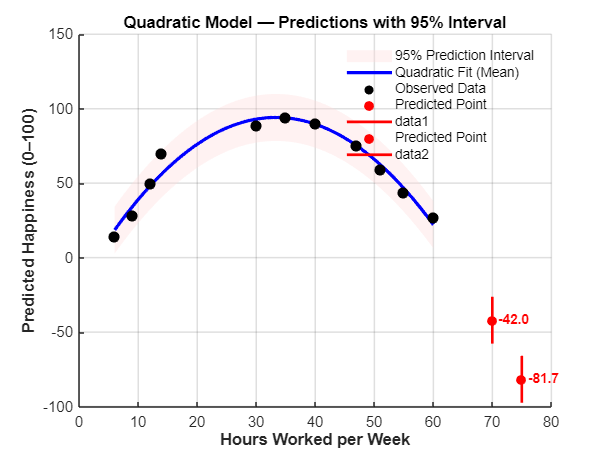


figure('Color','w'); hold on; grid on;

% Fitted curve (model mean)
xgrid = linspace(min(hours), max(hours), 400)';
Xgrid = [xgrid.^2, xgrid, ones(size(xgrid))];
ygrid = Xgrid * coef;

% Constant prediction interval bounds
SE_pred_py_const = 1.1 * RSE;
PI_low_py = ygrid - tcrit * SE_pred_py_const;
PI_upp_py = ygrid + tcrit * SE_pred_py_const;

% Shaded 95% prediction interval band
fill([xgrid; flipud(xgrid)], ...
     [PI_low_py; flipud(PI_upp_py)], ...
     [1.00 0.85 0.85], ...
     'EdgeColor','none','FaceAlpha',0.33, ...
     'DisplayName','95% Prediction Interval');

% Fitted quadratic mean curve
plot(xgrid, ygrid, 'b-', 'LineWidth',2.2, ...
     'DisplayName','Quadratic Fit (Mean)');

% Observed data points
scatter(hours, happiness, 55, 'k', 'filled', ...
        'DisplayName','Observed Data');

% Predicted points with intervals
for i = 1:height(PredictionSummary)
    x0 = PredictionSummary.Hours(i);
    y0 = PredictionSummary.Predicted_Happiness(i);
    L  = PredictionSummary.LowerBound(i);
    U  = PredictionSummary.UpperBound(i);

    % Marker for point prediction
    plot(x0, y0, 'ro', 'MarkerFaceColor','r', 'MarkerSize',6, ...
         'DisplayName','Predicted Point');

    % Vertical line for interval
    plot([x0 x0], [L U], 'r-', 'LineWidth',1.8);

    % Text label
    text(x0 + 1, y0, sprintf('%.1f', y0), ...
        'FontSize',9,'FontWeight','bold','Color','r');
end

xlabel('Hours Worked per Week','FontWeight','bold');
ylabel('Predicted Happiness (0–100)','FontWeight','bold');
title('Quadratic Model — Predictions with 95% Interval', ...
      'FontSize',13,'FontWeight','bold');
legend('Location','northeast','FontSize',9,'Box','off');
set(gca,'FontSize',10,'LineWidth',1);
hold off;

**Visualisation **

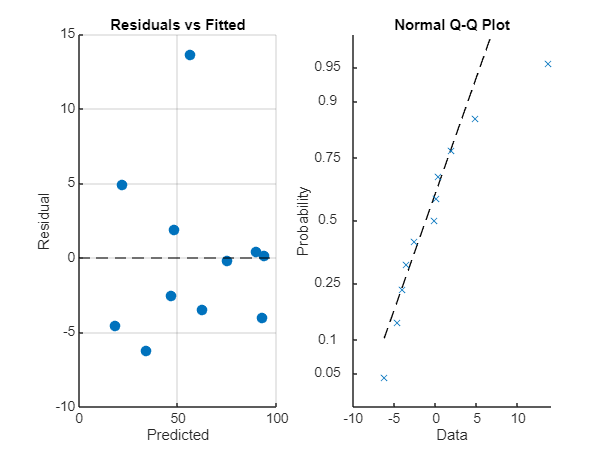

figure('Color','w');
tiledlayout(1,2,'TileSpacing','compact');

% Residuals vs Fitted
nexttile;
scatter(yhat, res,50,'filled'); hold on; yline(0,'k--');
title('Residuals vs Fitted'); xlabel('Predicted'); ylabel('Residual'); grid on;

% Q-Q Normality Plot
nexttile;
probplot('normal',res); title('Normal Q-Q Plot');

## Step 10. Decision-Making Summary 

Decision for this dataset:

fprintf('\n=== Model Decision Summary ===\n');


=== Model Decision Summary ===


fprintf('• Happiness peaks then decreases → diminishing returns.\n');

• Happiness peaks then decreases → diminishing returns.


fprintf('• Quadratic model statistically significant (F-test).\n');

• Quadratic model statistically significant (F-test).


fprintf('• Both terms meaningful → hours both help and hurt wellbeing.\n');

• Both terms meaningful → hours both help and hurt wellbeing.


fprintf('• Predictions for 70-75 hours show decline → burnout zone.\n');

• Predictions for 70-75 hours show decline → burnout zone.


fprintf('• AI wellbeing systems must prevent harmful work hours.\n');

• AI wellbeing systems must prevent harmful work hours.


fprintf('================================\n');

**Happiness rises with more work**

…but **after ~35–40 hours per week**, extra work **reduces happiness**.

This mirrors:

- Work–life balance research

- Burnout in occupational psychology

- Ethical AI wellbeing recommendations